# 1CWK50 submission

Full instructions on how to submit this live script are available in the assignment specification on Moodle ("How to submit your work" section). Make sure you read them carefully, and that you test your final submission thoroughly before uploading it to Moodle. No additional files can be accepted after the deadline has passed.

## 1. Dataset preparation (20%)

Section1 = "Dataset preparation (20%)"

Section1 = "Dataset preparation (20%)"

% check the dataset is present:
if ~exist('moons.csv', 'file')
    error('You need to download moons.csv from Moodle and place it into the same directory as this live script');
end

rng(0); % re-seed the random number for reproducible results

% add your code on the lines below:

data = readcell('moons.csv'); %read dataset from file 
data(1:1:10, 1:1:end)   %look at first 10 rows to identify headings 

ans = 10×3 cell array
    {'Feature 1'}    {'Feature 2'}    {'Label'  }
    {[   0.1567]}    {[   1.3182]}    {'Class A'}
    {[  -0.9705]}    {[   0.6211]}    {'Class A'}
    {[  -0.9086]}    {[   0.1598]}    {'Class A'}
    {[   0.7076]}    {[   0.2604]}    {'Class A'}
    {[  -1.2325]}    {[   0.9279]}    {'Class A'}
    {[  -0.6282]}    {[   0.8368]}    {'Class A'}
    {[   0.6124]}    {[   0.2656]}    {'Class A'}
    {[  -0.7009]}    {[  -0.0706]}    {'Class A'}
    {[   1.2655]}    {[   1.3637]}    {'Class A'}


obs = data(2:end,:)     %drop the feature name headings 

obs = 150×3 cell array
    {[ 0.1567]}    {[ 1.3182]}    {'Class A'}
    {[-0.9705]}    {[ 0.6211]}    {'Class A'}
    {[-0.9086]}    {[ 0.1598]}    {'Class A'}
    {[ 0.7076]}    {[ 0.2604]}    {'Class A'}
    {[-1.2325]}    {[ 0.9279]}    {'Class A'}
    {[-0.6282]}    {[ 0.8368]}    {'Class A'}
    {[ 0.6124]}    {[ 0.2656]}    {'Class A'}
    {[-0.7009]}    {[-0.0706]}    {'Class A'}
    {[ 1.2655]}    {[ 1.3637]}    {'Class A'}
    {[ 0.4948]}    {[ 0.9364]}    {'Class A'}
    {[-0.5249]}    {[ 1.0001]}    {'Class A'}
    {[-0.8581]}    {[ 0.2206]}    {'Class A'}
    {[-1.3395]}    {[-0.3469]}    {'Class A'}
    {[ 0.9408]}    {[ 0.1181]}    {'Class A'}
    {[-1.4020]}    {[ 0.4198]}    {'Class A'}
    {[ 0.4201]}    {[ 0.7488]}    {'Class A'}


obs_shuffled = obs(randperm(size(obs,1)), :);   %shuffle observations 

nTest = round(0.4 * size(obs_shuffled,1))   %how many needed for 40% split for testing

nTest = 60


obs_test = obs_shuffled(1:1:nTest, :);  %copy first 40% for testing 
obs_train = obs_shuffled(nTest+1:1:end, :); %copy remaining 60% for training 

label_index = 3; %set column index for target feature 


test_labels = categorical(obs_test(:, label_index)); %split test labels and examples
test_examples = cell2mat(obs_test(:, 1:end~=label_index));  

size(test_examples) %size checks 

ans =     60     2


size(test_labels)

ans =     60     1




train_labels = categorical(obs_train(:, label_index));  %split training labels and examples
train_examples = cell2mat(obs_train(:, 1:end~=label_index));

size(train_examples) %size checks 

ans =     90     2


size(train_labels)

ans =     90     1




%do you want any outputs or everything hidden? Size checks etc

## 2. Feature space visualisation (20%)

Section2 = "Abstraction visualisations (20%)"

Section2 = "Abstraction visualisations (20%)"

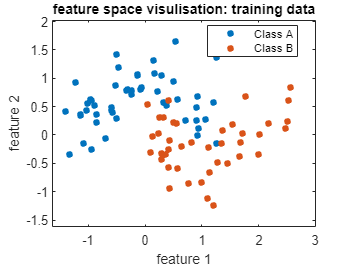

rng(0); % re-seed the random number for reproducible results

% add your code on the lines below:

m_nb = fitcnb(train_examples, train_labels); % train the Naive Bayes classifier 
predictions = m_nb.predict(test_examples); %use NB classifier to create the prections based off the test data 
p_nb = sum(predictions == test_labels) / length(test_labels); %measure performance of predictions (testing) 


figure;  % open a new figure 
gscatter(m_nb.X(:,1), m_nb.X(:,2), m_nb.Y); %plot data 
xlabel('feature 1')                         %label the axis 
ylabel('feature 2')             
title('feature space visulisation: training data')  %add title 
axis('equal')                                       %set axis 

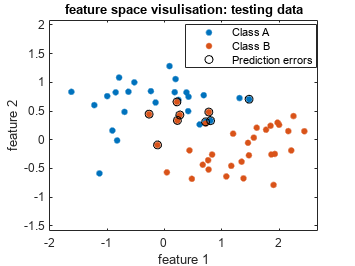



figure;  % open a new figure 
gscatter(test_examples(:,1), test_examples(:,2), test_labels);
xlabel('feature 1') %label the axis 
ylabel('feature 2')
title('feature space visulisation: testing data')
axis('equal')
hold('on'); % allow you to overlay 
wrong = find(predictions~=test_labels); % work out when the preiction is not equal to the test label 
scatter(test_examples(wrong,1), test_examples(wrong,2) , 'ok', 'DisplayName', 'Prediction errors') %plot these points 

## 3. Abstraction visualisations (20%)

Section3 = "Abstraction visualisations (20%)"

Section3 = "Abstraction visualisations (20%)"

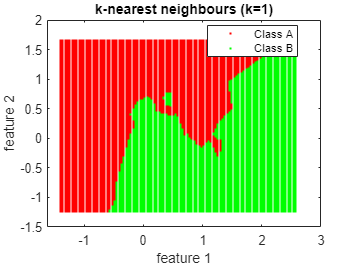

rng(0); % re-seed the random number for reproducible results

% add your code on the lines below:

%visualise_abstraction2 is without the use of meshgrid and is used for all of the outputs
%version with meshgrid can also be seen called just visualise_abstraction if neeed


m_knn = fitcknn(train_examples, train_labels, 'NumNeighbors', 1);           %set for k =1 
visualise_abstraction2(m_knn);                                              %pass to visualise 
xlabel('feature 1');                                                        %axis label
ylabel('feature 2');                                                        %axis label
title('k-nearest neighbours (k=1)');                                        %title

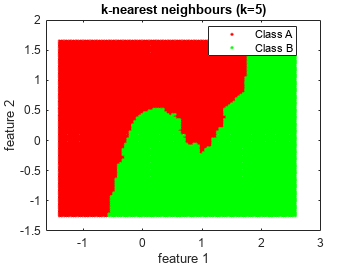



m_knn = fitcknn(train_examples, train_labels, 'NumNeighbors',5);            %set for k =5 
visualise_abstraction2(m_knn);
xlabel('feature 1');
ylabel('feature 2');
title('k-nearest neighbours (k=5)');

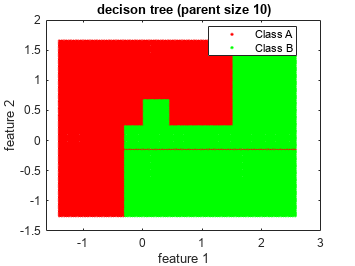



m_dt = fitctree(train_examples, train_labels, 'MinParentSize',10, 'MergeLeaves', 'off', 'Prune', 'off');    %set min parente to 10 , no merge , no pruning
visualise_abstraction2(m_dt);                                               %pass to visualise 
xlabel('feature 1');                                                        %axis label
ylabel('feature 2');                                                        %axis label
title('decison tree (parent size 10)');                                     %title 

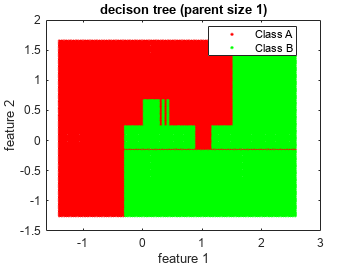



m_dt = fitctree(train_examples, train_labels, 'MinParentSize',1, 'MergeLeaves', 'off', 'Prune', 'off');    %set min parente to 1 , no merge , no pruning
visualise_abstraction2(m_dt);
xlabel('feature 1');
ylabel('feature 2');
title('decison tree (parent size 1)');

## 4. Classifier re-implementations (20%)

Section4 = "Classifier re-implementations (20%)"

Section4 = "Classifier re-implementations (20%)"

rng(0); % re-seed the random number for reproducible results

% add your code on the lines below:

%using my own implimentation of knn which doesnt use knnsearch etc 
mym_knn = my_fitcknn(train_examples, train_labels, 'NumNeighbors', 1);         %k = 1
visualise_abstraction2(mym_knn);                                               %visualise  
xlabel('feature 1');                                                           %axis label 
ylabel('feature 2');
title('k-nearest neighbours (k=1)');                                           %title 


mym_knn = my_fitcknn(train_examples, train_labels, 'NumNeighbors', 5);         %k=5
visualise_abstraction2(mym_knn);
xlabel('feature 1');
ylabel('feature 2');
title('k-nearest neighbours (k=5)');

## 5. Extension to ensembles (20%)


Section5 = "Ensembles (20%)"

Section5 = "Ensembles (20%)"

rng(0); % re-seed the random number for reproducible results

% add your code on the lines below:


m_en = my_fitcensemble(train_examples, train_labels);           %pass to ensemble 
predictions_en = m_en.predict(test_examples);                   %predictions it generates using knn and nb 
p_en = sum(predictions_en == test_labels) / length(test_labels);  %measure performance of predictions (testing) 


%visualise the ensemble of nb and knn 
visualise_abstraction2(m_en)            
xlabel('feature 1');
ylabel('feature 2');
title('soft voting NB + KNN');

%------- testing /checking if my outputs are the same as built in -------- 
%my knn showing scores and predictions
mym_knn = my_fitcknn(train_examples, train_labels, 'NumNeighbors', 5);
[mym_knn_predictions, mym_knn_scores] = mym_knn.predict(test_examples);
p_knn = sum(mym_knn_predictions == test_labels) / length(test_labels);
mym_knn_scores;

%built in knn to compare with 
[predictions_knn, scores_knn] = m_knn.predict(test_examples);
scores_knn;
predictions_knn;
p_knn2 = sum(predictions_knn == test_labels) / length(test_labels);


%my NB showing scores and predictions
mym_nb = my_fitcnb(train_examples, train_labels);
[mym_nb_predictions, mym_nb_scores] = mym_nb.predict(test_examples);
mym_nb_predictions = transpose(mym_nb_predictions);
mym_nb_scores;
p_nb = sum(mym_nb_predictions' == test_labels) / length(test_labels);

%built in nb to compare 
[predictions_nb, scores_nb] = m_nb.predict(test_examples);
scores_nb;
p_nb2 = sum(predictions_nb == test_labels) / length(test_labels);










